# Torque control

In this section, the model parameters will be defined, followed by the implementation of the standard PI controller in both continuous-time and digital versions. Lastly, anti-windup will be implemented using back-calculation and tracking.

## Motor parameters

This section initializes and documents fundamental motor parameters used for subsequent modeling and control tasks. 

clear; close all; clc
%% Motor parameters

k_t = 1.32 % N*m/A

k_t = 1.3200

R_a = 2.1 % Ohm

R_a = 2.1000

k_e = 1.32 % V*s/rad

k_e = 1.3200

L_a = 2.3/1000  % mH

L_a = 0.0023

G_v=1

G_v = 1

## PI Design with PID Tuner

This section is dedicated to designing and implementing PI controller for torque control of DC motor. 

The inital C_start controller is synthesized with MATLAB's PID Tuner in Control System Designer to obtain a Proportional-Integral (PI) controller tailored for torque control. 

#### PI Controller Time-Continous obtained with PID Tuner

s=tf("s")

s =
 
  s
 
Continuous-time transfer function.
Model Properties



%Process tf 
P= 1 /(s*L_a + R_a)

P =
 
        1
  --------------
  0.0023 s + 2.1
 
Continuous-time transfer function.
Model Properties



%PI Controller tf
C_start=(2.0811*(s+91.3)) / s

C_start =
 
  2.081 s + 190
  -------------
        s
 
Continuous-time transfer function.
Model Properties


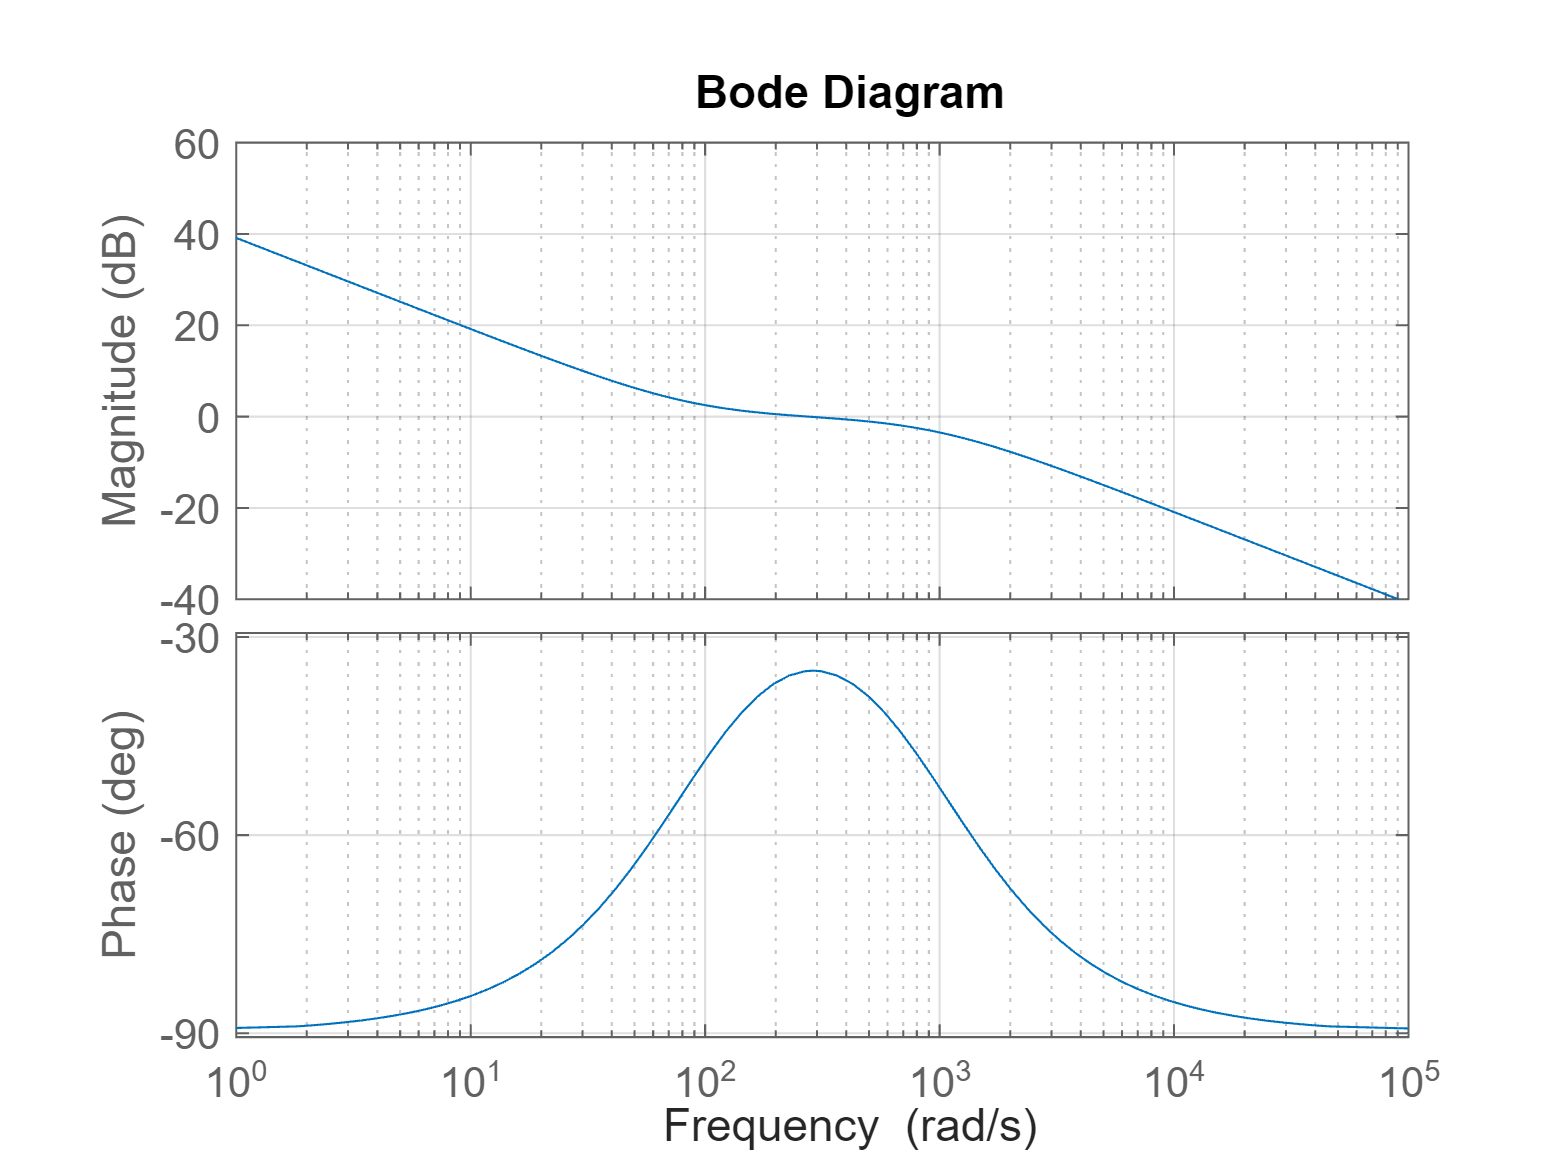


H=1;

G_start= C_start*P;

%Open Loop transfer function
F_start = C_start*P*H;

%Plotting Bode Diagram for checking stability and robustness margin.
bode(F_start)
grid on


%Closed Loop transfer function
W_start = G_start/(1+F_start)

W_start =
 
         0.004787 s^3 + 4.807 s^2 + 399 s
  ----------------------------------------------
  5.29e-06 s^4 + 0.01445 s^3 + 9.217 s^2 + 399 s
 
Continuous-time transfer function.
Model Properties


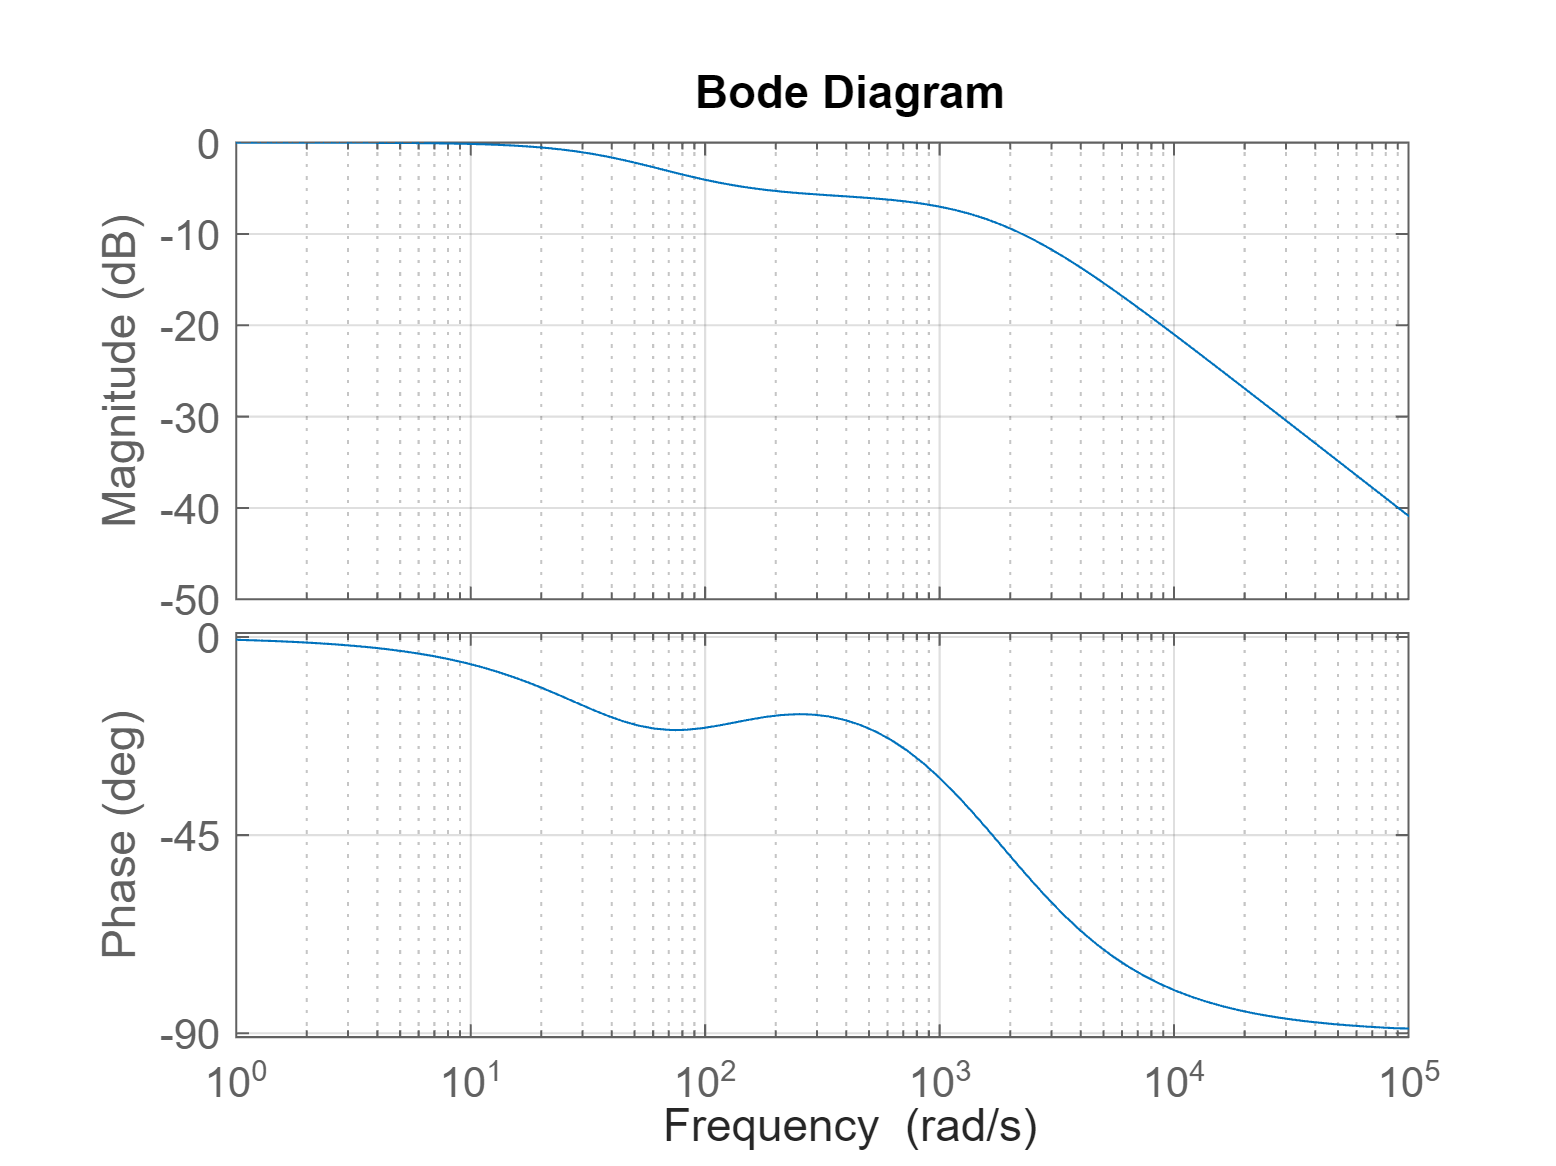


figure 
bode(W_start)
grid on


cc_bandwidth_start= bandwidth(W_start)

cc_bandwidth_start = 67.0596

#### Digital version of PI obtained using PID Tuner

Ts = 0.005;
C_z_start=c2d(C_start,Ts,'tustin');

#### Discretization Delay

From Bode diagram $\omega_c =275\;\frac{\textrm{rad}}{s}$ and $m_{\phi } =145\degree$

w_c_1=275

w_c_1 = 275

phase_margin_1=145

phase_margin_1 = 145

discretization_delay_1 = 3/2* w_c_1*Ts*(180/pi)

discretization_delay_1 = 118.1725

phase_margin_minus_delay_1 = phase_margin_1 - discretization_delay_1

phase_margin_minus_delay_1 = 26.8275

## PI Fine-tuning

This section is dedicated to fine-tuning PI controller obtained with PID Tuner.

The starting PI controller was adjusted to achieve a lower crossover frequency ($\omega_c$) due to upcoming discretization delay, ensuring that the phase margin was preserved to prevent instability.

The section subsequently computes and plot the Bode diagrams of the open-loop transfer function, Bode diagrams of the closed-loop transfer function, and closed-loop bandwidth. 

This approach ensures robust control performance ensuring a better phase margin also with discretization delay.

#### PI Controller Time-Continous 

s=tf("s")

s =
 
  s
 
Continuous-time transfer function.
Model Properties



%Process tf 
P= 1 /(s*L_a + R_a)

P =
 
        1
  --------------
  0.0023 s + 2.1
 
Continuous-time transfer function.
Model Properties



%PI Controller tf
C=(1.8*(s+91.3)) / s

C =
 
  1.8 s + 164.3
  -------------
        s
 
Continuous-time transfer function.
Model Properties



H=1;

G= C*P;

%Open Loop transfer function
F = C*P*H;

%Plotting Bode Diagram for checking stability and robustness margin.
bode(F_start)
grid on


%Closed Loop transfer function
W = G/(1+F)

W =
 
         0.00414 s^3 + 4.158 s^2 + 345.1 s
  -----------------------------------------------
  5.29e-06 s^4 + 0.0138 s^3 + 8.568 s^2 + 345.1 s
 
Continuous-time transfer function.
Model Properties


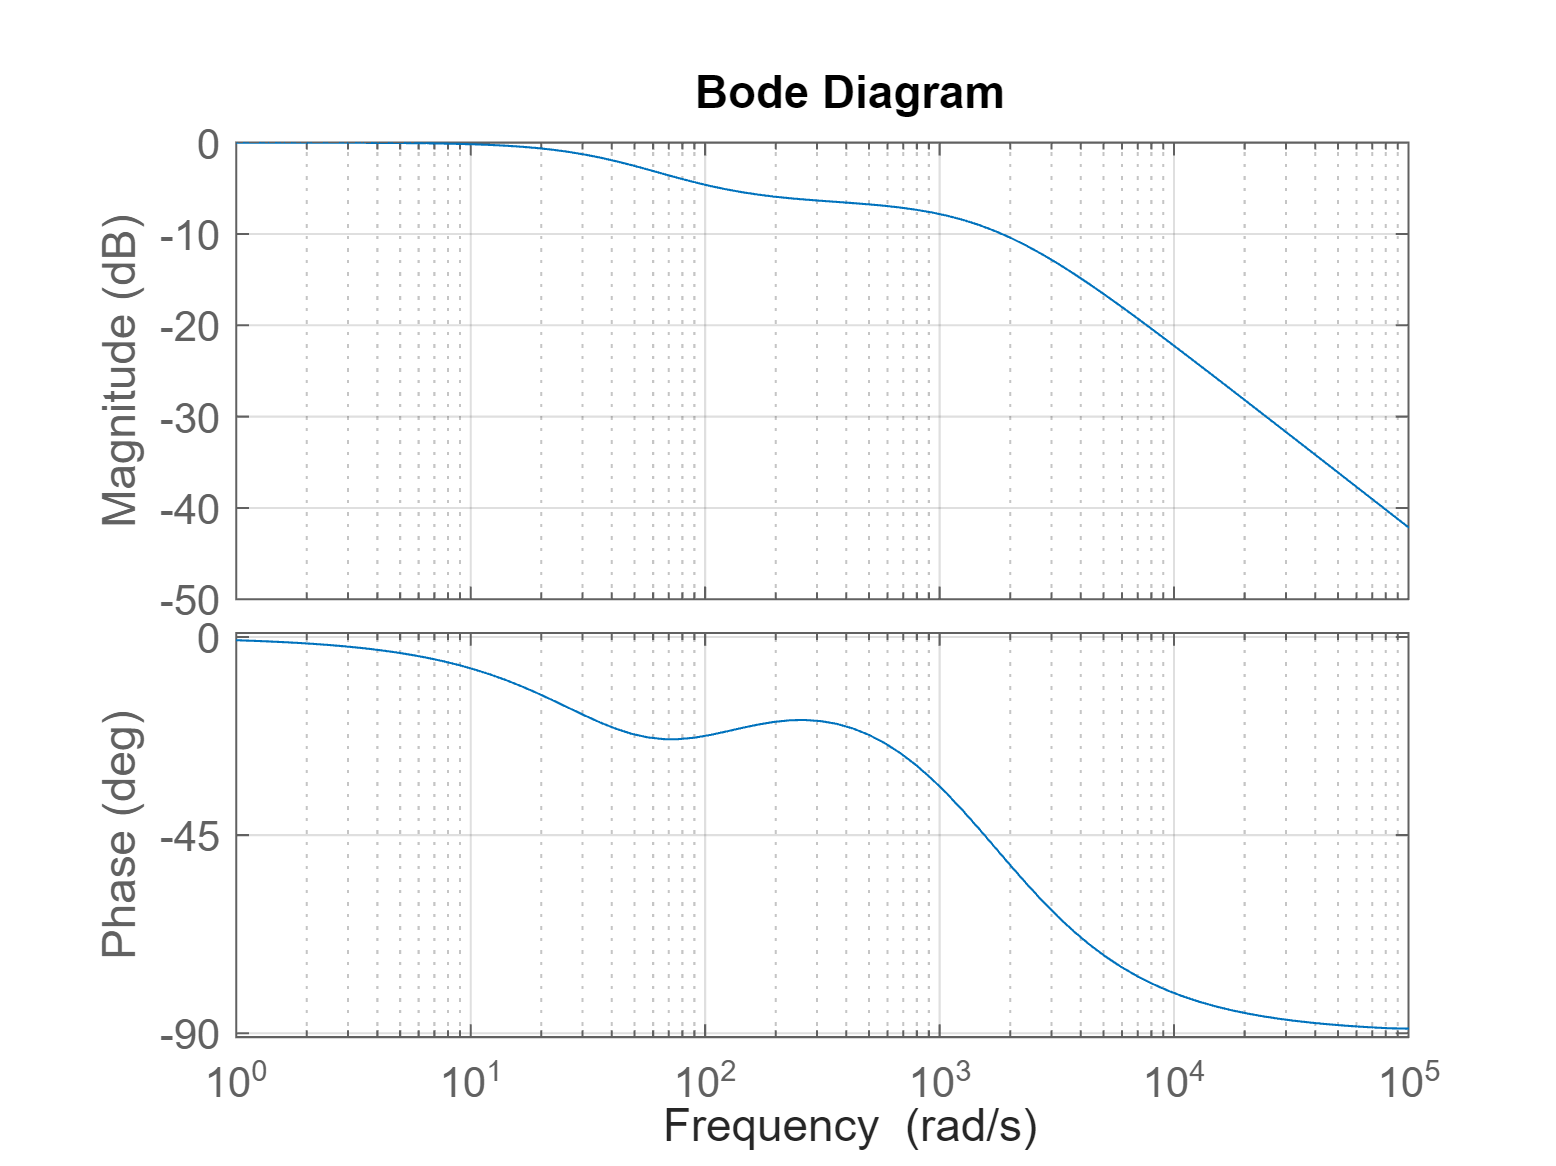


figure 
bode(W)
grid on


cc_bandwidth= bandwidth(W)

cc_bandwidth = 57.9393

#### Digital version of PI obtained using PID Tuner

Ts = 0.005;
C_z=c2d(C,Ts,'tustin');

#### Discretization Delay

From Bode diagram $\omega_c =145\;\frac{\textrm{rad}}{s}$ and $m_{\phi } =139\degree$

w_c_2 = 145

w_c_2 = 145

phase_margin_2=139

phase_margin_2 = 139

discretization_delay_2 = 3/2* w_c_2*Ts*(180/pi)

discretization_delay_2 = 62.3092

phase_margin_minus_delay_2 = phase_margin_2 - discretization_delay_2

phase_margin_minus_delay_2 = 76.6908

## Antiwindup with back-calculation and tracking

In this section, anti-windup measures are implemented for a discrete-time control system with a sampling period Ts=0.005 seconds:

- **Controller Transfer Function Decomposition:**

- The transfer function of the PI controller $C_z
$ is decomposed into numerator and denominator coefficients stored in $Q\_vec
$ and $P\_vec
$, respectively.

- **Discrete-Time Equivalent:**

- $z\_Q\_Gamma
$ represents the discrete-time equivalent of the numerator coefficients $Q\_vec
$  with a unit step input $\Gamma \_vec=[1  0]$ at the sampling period Ts.

- **Anti-Windup Function:**

- $z\_antiwindupFunc
$ computes the discrete-time anti-windup function, which adjusts for integrator windup by considering the difference between $\Gamma \_vec$ and $P\_vec
$ over the sampling period Ts.

These steps ensure that the controller maintains stability and performance by mitigating the effects of integrator windup in the discrete-time control system.

%% Windup
Ts=0.005;

[Q_vec,P_vec] = tfdata(C_z,'v');

Gamma_vec = [1 0];

z_Q_Gamma = tf(Q_vec,Gamma_vec,Ts);

z_antiwindupFunc = tf(Gamma_vec-P_vec,Gamma_vec,Ts);

## Simulation

In this section the model is simulated and the results are showed. In addition to dynamic and steady-state performance, it is possible to observe disturbance rejection.

simulation = sim('torque_control_simulation_sm.slx')

simulation =   Simulink.SimulationOutput:

                    ref: [1x1 timeseries] 
                 torque: [1x1 timeseries] 
                   tout: [5729x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


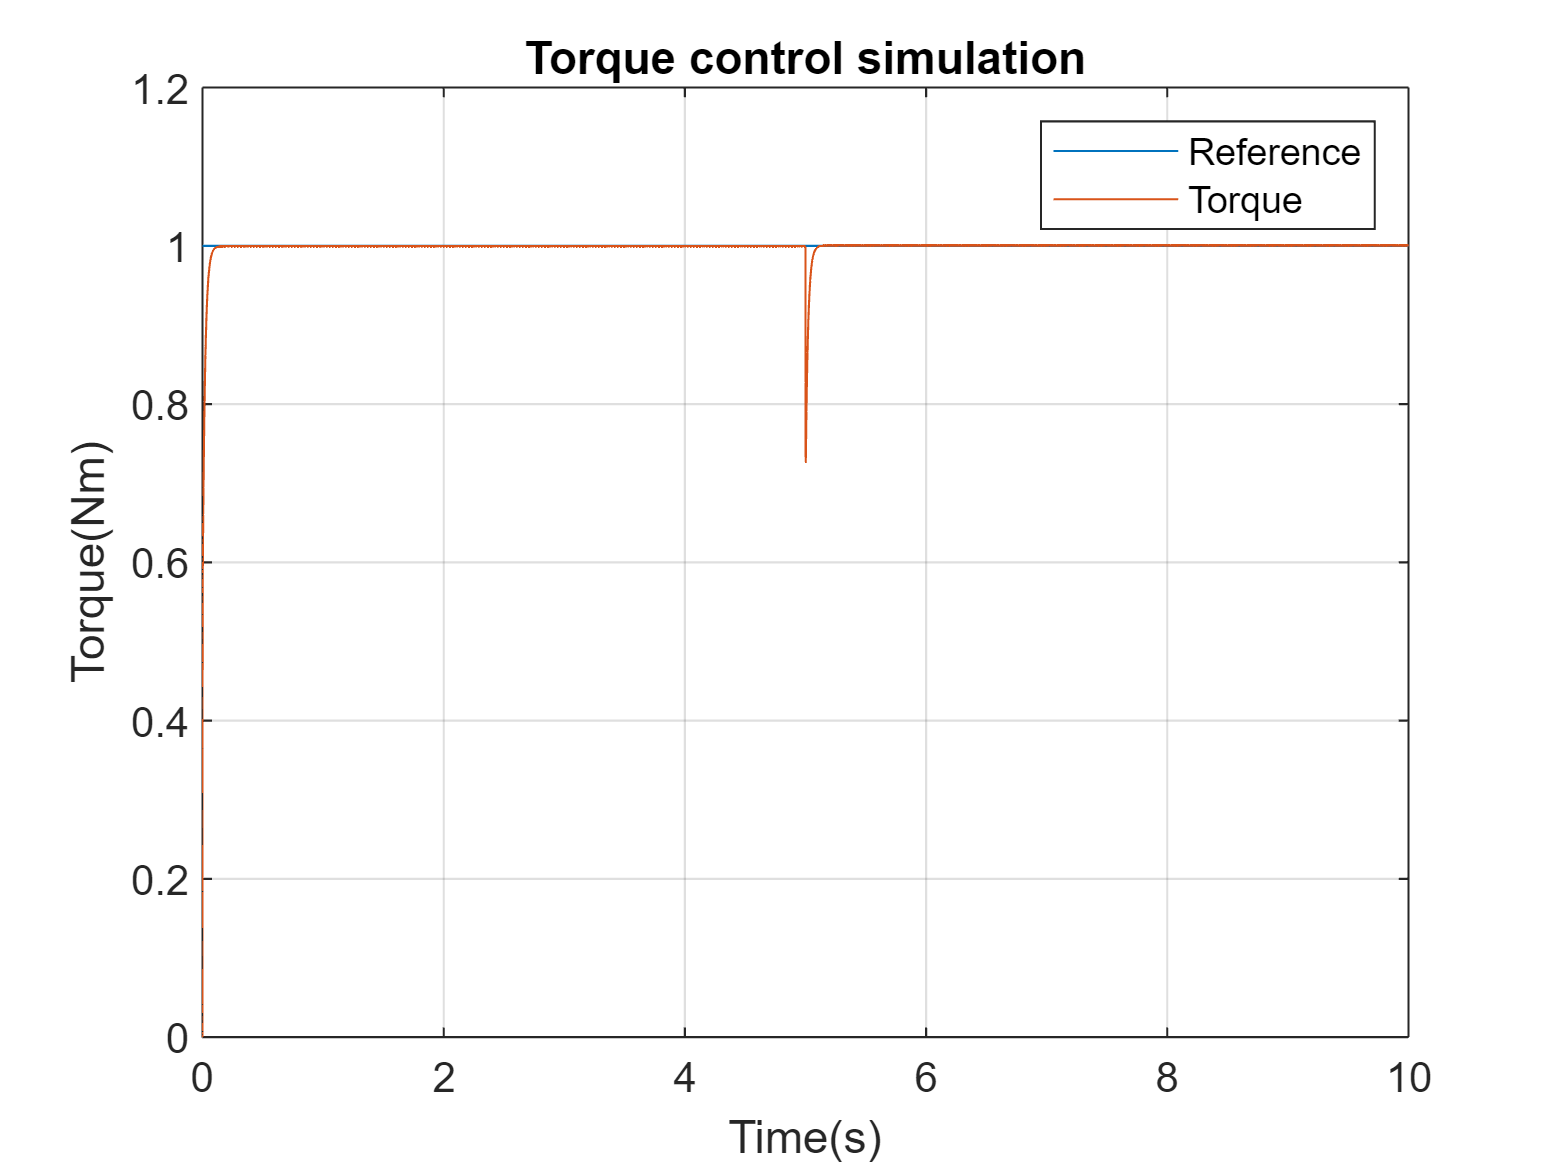

figure
plot(simulation.ref)
hold on
plot(simulation.torque)

xlabel('Time(s)');
ylabel('Torque(Nm)');
title('Torque control simulation');

sim_Strings{1} = ['Reference'];
sim_Strings{2} = ['Torque'];

legend(sim_Strings);

grid on;